**Run JSNMF algorithm on mouse kidney (RNA+ATAC, sci-CAR) data**

**Load data, including single-cell transciptome and epigenomic proiles. **

Data preprocessing using R package "Seurat 4.0", preprocessed data was used in the analysis below. We provide script "preprocessing.R" to conduct data preprocess, normalization and hingh variable gene selection steps in R enviroment

addpath('../data')
load('kidney_5k_10k.mat')
load('housekeeping_genes.mat')
load('Kidney_sciCAR_data.mat','RNA')

**Preparing for computing RAGI**

[~,ix1,ix2]=intersect(share_bd,RNA.Cells,'stable');
genes = RNA.Features; data = RNA.data;
data = data(:,ix2);
sM = sum(data,2); zero_row = find(sM==0);
data(zero_row,:) = []; genes(zero_row) = [];
data = data./repmat(sum(data),size(data,1),1)*10000;
data = log(data+1);

label_name = label;
num_clu = length(unique(label_name));
tag = unique(label_name); tag = cellstr(tag);
[~, label] = ismember(label_name,tag);

**marker genes are given by the original publication; house-keeping genes are provided in the website "http://www.housekeeping.unicamp.br/"**

marker_genes = ["Slc12a3";'Trpm6';'Abca13';'Klhl3';'Wnk1';'Tsc22d1';'Cadps2';...
    'Egfem1';'Calb1';'Kl';'Temem72';'Dach1';'Ptprm';'Sgms2';'Tox3';'Frmpd4';...
    'Rbms3';'Fxyd4';'Dnm3';'Cacnb2';'Pde1c';'Pde8b'];
[~,~,ind1] = intersect(marker_genes,genes,'stable');
[~,~,ind2] = intersect(hp_genes,genes,'stable');
data = sparse(data);
clear ix1 ix2 sM zero_row tag share_bd RNA marker_genes hp_genes genes

** Parameter selection **

addpath('../codes')
addpath('../external')
[alpha,gamma,Inits] = parameter_selection(X1,X2,label);

disp(['value of alpha:',num2str(alpha)]);

value of alpha:0.31629


disp(['value of gamma:',num2str(gamma)]);

value of gamma:3287.3936


**Start time**

tic
[W1,W2,H1,H2,S,iter,objs] = jsnmf(X1,X2,alpha,gamma,Inits);

iteration starts!
number of iteration:10  obj:3730831.8015
number of iteration:20  obj:3720740.5389
number of iteration:30  obj:3717563.2642
number of iteration:40  obj:3715983.1244
number of iteration:50  obj:3715001.5325
number of iteration:60  obj:3714346.0563
number of iteration:70  obj:3713900.8529
converged!


disp('JSNMF runtime:');

JSNMF runtime:


toc

Elapsed time is 162.382499 seconds.


**Evaluating performance**

% KNN on S, k is insensitive to the performance, here we suggested k=50
A = Wtrim(S,50); 
% implement louvain clustering
[clust,~,~] = getNCluster(A,num_clu,0,3,20); 
if length(unique(clust))== num_clu
   [ac, nmi_value, ~] = CalcMetrics(label, clust);
   [ave_mk_gini, ave_hk_gini, difgini] = RAGI(data,ind1,ind2,clust);
else
% using spectral clustering instead if number of clusering doesn't equals to the pointed number
   [~, clust, ~] = SpectralClustering(A, num_clu); 
   [ac, nmi_value, ~] = CalcMetrics(label, clust);   
   [ave_mk_gini, ave_hk_gini, difgini] = RAGI(data,ind1,ind2,clust);
end

ac: 0.6072	1867/4753	nmi:0.5415	


ave_marker_gene: 0.5968	ave_hk_gini:0.1550	diff_gini:0.4418	


**Downstream analysis including visualization**

**visualization on S obtained from JSNMF**

Parallelizing UMAP with MATLAB's 8 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v2.1.3
(ub=basic, us=supervised, ubt=template, ust=supervised template)
UMAP(method=MEX, n_neighbors=15, n_components=2, metric='precomputed', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.3, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.992174408960354, b=1.11225576844318, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='precomputed', dist_args=[]


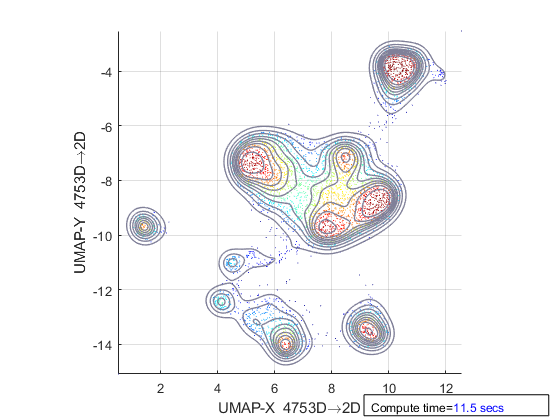

UMAP reduction finished (cost 11.5 secs)
 Finished basic (ub) reduction


% load UMAP package
addpath('../umapFileExchange/umap') 
addpath('../umapFileExchange/util')

term = '.'; 
colors = generateColors(max(length(unique(label_name))),length(unique(term)));

D_jsnfm = 1-S; D_jsnfm = D_jsnfm-diag(diag(D_jsnfm));
[reduction_jsnmf, ~, ~, ~] = run_umap(D_jsnfm,'metric','precomputed'); 

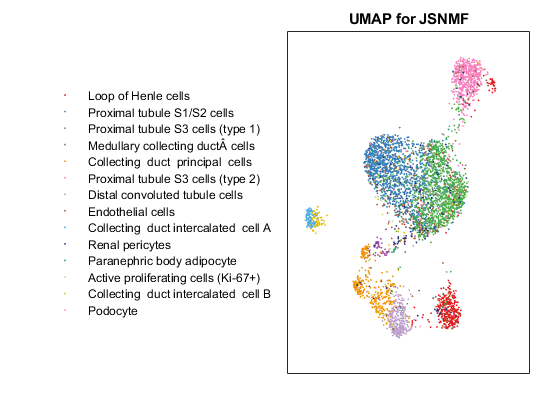

gscatter(reduction_jsnmf(:,1),reduction_jsnmf(:,2),label_name,colors,[],4); 
set(gca,'xtick',[],'ytick',[]);
title('UMAP for JSNMF')

legend('Location','westoutside','Box','off','FontSize',9.5); 
legendmarkeradjust(16)
legend('boxoff')

**Preparing for gene ontology (GO) enrichment analysis**

% analysis on W1
W1 = full(W1);
% normalization is not necessary
% W1_norm = W1 * diag(1./sqrt(sum(W1.^2)));

% sort each column of W1 to find key genes
[B, I] = sort(W1, 1, 'descend');
nfactor = size(W1, 2);

**loading genes and peaks**

load('kidney_5k_10k.mat','genes','peaks')

% selecting top 200 genes with large values
topk = 200; 
IX = cell(topk+1, 1); 
IX{1} = 'gene symbol';

% save top genes for each factor, and these genes can be used for pathway
% enrichment analysis.

% need to construct Directory 'kidney\W1' in advance
for i = 1:nfactor
   filenm = ['kidney\W1\factor_' num2str(i) '.csv'];
   IX(2:end) = genes(I(1:topk, i));
   dlmcell(filenm, IX);
   disp(['Successfully write factor_',num2str(i),' for gene enrichment analysis']);
end

Successfully write factor_1 for gene enrichment analysis
Successfully write factor_2 for gene enrichment analysis
Successfully write factor_3 for gene enrichment analysis
Successfully write factor_4 for gene enrichment analysis
Successfully write factor_5 for gene enrichment analysis
Successfully write factor_6 for gene enrichment analysis
Successfully write factor_7 for gene enrichment analysis
Successfully write factor_8 for gene enrichment analysis
Successfully write factor_9 for gene enrichment analysis
Successfully write factor_10 for gene enrichment analysis
Successfully write factor_11 for gene enrichment analysis
Successfully write factor_12 for gene enrichment analysis
Successfully write factor_13 for gene enrichment analysis
Successfully write factor_14 for gene enrichment analysis



% analysis on W2(region loading)
% check peaks with abnormal name, such as {'chrUn-GL456239-39648-39894'},
% these peaks should be removed from peak list
% peaks(1101,:) = []; 
[B,I] = sort(W2, 1,'descend');
nfactor = size(W2,2);
topk = 1000;
IX = cell(topk,nfactor);
loci = cell(topk,3);

% check peak names with special symbols
peaks = strrep(peaks,':','-');

% need to construct Directory 'kidney/W2' in advance
for i = 1:nfactor
   IX(:,i) = peaks(I(1:topk,i),:);
   IX(:,i) = regexp(IX(:,i), '-', 'split');
   filenm = ['kidney\W2\factor_' num2str(i) '.bed' ];
   for j = 1:topk
       loci{j, 1} = char(IX{j,i}{1,1});
       loci{j, 2} = char(IX{j,i}{1,2});
       loci{j, 3} = char(IX{j,i}{1,3});
       dlmcell(filenm, loci);
   end
   disp(['Successfully write factor_',num2str(i),' for region enrichment analysis']);
   
end

Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analysis
Successfully write factor_1 for region enrichment analys


% after obtaining genes from W1 and peaks from W2, gene ontology (GO) enrichment analyis
% can be implemented using some online tools, such as GREAT, Metascape and
% so on
